# II. Quantum EigenModes of a Potential

Schrodinger equation: 


$$i\hbar\frac{\partial\Psi}{\partial t} = -\frac{\hbar^2}{2m}\frac{\partial^2\Psi}{\partial z^2} + V(z)\Psi$$


When we consider the time dependent wavefunction to be representable as $\Psi(z,t) = \psi(z)e^{-iEt/\hbar}$ then we can write the time independent schrodinger equation as 


$$E_j \psi_j(z) = -\frac{\hbar^2}{2m}\frac{d^2\psi_j}{dz^2} + V(z)\psi_j\quad,\quad j = 0,1,2,3,\dots$$


We'll represent the solutions to this equation for the quantum harmonic oscillator as the hermite guassian solution set. 

$\psi_j(z) = \mathcal{N}_j H_j(z\,/\,z_0)e^{-z^2/2z_0^2}$ where the oscillator length is $z_0 = \sqrt{\frac{\hbar}{m\omega}}$ and $z_j = z_{0}\sqrt{2j + 1}$ 

In order to approach the problem numerically, we need continuous space into a set of discrete points given by $z_\mu = \frac{z_{max}}{2} + (\mu -1)\Delta z\quad,\quad \mu = 1,2,\dots,N$ where $\Delta z = z_{max}/(N-1)$

The second approximation is performed on the second derivative $\frac{d^2\psi}{dz^2}\rightarrow \frac{(\psi_{\mu+1} - 2\psi_\mu +\psi_{\mu-1})}{\Delta z^2}$ such that we can write the hamiltonian as 


$$H_{\mu,\nu} = \bigl[V_\mu + \frac{\hbar^2}{m\Delta z^2}\bigl]\delta_{\mu,\nu} - \frac{\hbar^2}{2m\Delta z^2}[\delta_{\mu,\nu +1} + \delta_{\mu,\nu - 1}]$$


$\Delta z << z_0$ and $z_{max} >> z_0$

b.) We know that the normalization condition for the wavefunction in coordinate space is 


$$1 = \int_{-\infty}^{\infty} |\Psi(z)|^{2}dz$$


We also know that produces normalized eigenvectors that satisfy a normalization condition: 


$$1 = \sum\limits_{\mu}|\upsilon_{\mu}|^{2}$$


We can then infer that the eigenvectors produced by matlab from the discrete matrix representation of the hamiltonian does not directly produce something that is a wavefunction.

To remedy this issue, we look at discretizing the normalization condition for the coordinate space wavefunction. 


$$\int_{-\infty}^{\infty} |\Psi(z)|^{2}dz \rightarrow \sum\limits_{\mu}\Delta z |\Psi_{\mu}|^{2}= 1$$


We now have a relationship between the wavefunction and the eigenvectors in matlab. 


$$\sum\limits_{\mu}\underbrace{\Delta z|\Psi_{\mu}|^{2}}_{|\upsilon_{\mu}|^{2}}= 1$$


Therefore we can find the wavefunctions by making use of the following relationship: 


$$\Psi_{\mu} = \frac{\upsilon_{\mu}}{\sqrt{\Delta z}}$$


## C. Quantum harmonic oscillator

b.)  

clear; close all;
z0 = 1e-6;   % beam width of 1um

I will choose $\Delta z = z_0/10$ and $z_{max} = 10z_0$

deltaZ = z0/10;     % step size
zmax = 10*z0;        % maximum grid extent
N = zmax/deltaZ + 1        % number of points in grid

N = 101

This means that there will be 101 eigenvalue/eigenvector pairs for `eigs` to compute.

mu = 1:N;
z_mu = -zmax/2 + (mu -1)*deltaZ;
h = zeros(N,N);
% create the hamiltonian matrix h
for i = 1:N
    for j = 1:N
        if i == j
            h(i,j) = (1/2)*(z_mu(i)/z0)^2 + (z0/deltaZ)^2;
        elseif i ==(j+ 1) || i == (j - 1)
            h(i,j) = -(1/2)*(z0/deltaZ)^2;
        end
    end
end

I will label the eigenvectors as `V = PSI` and the eigenvalues as `D = E`

% find eigenvectors and eigenvalues
[PSI,E] = eigs(h,N,'smallestabs')

PSI =     0.0000   -0.0000   -0.0000    0.0001    0.0002   -0.0006   -0.0015    0.0031    0.0060   -0.0104   -0.0163    0.0230    0.0301   -0.0371   -0.0436    0.0496    0.0551   -0.0603   -0.0652    0.0698    0.0742   -0.0784   -0.0824    0.0862    0.0899   -0.0935   -0.0969    0.1002    0.1034   -0.1064   -0.1093    0.1121    0.1147   -0.1172   -0.1196    0.1218    0.1239   -0.1259   -0.1278    0.1295    0.1311   -0.1326   -0.1339    0.1351    0.1362   -0.1371   -0.1379    0.1385    0.1391   -0.1395
    0.0000   -0.0000   -0.0000    0.0002    0.0005   -0.0013   -0.0031    0.0066    0.0126   -0.0215   -0.0332    0.0465    0.0602   -0.0731   -0.0848    0.0951    0.1042   -0.1121   -0.1190    0.1250    0.1302   -0.1347   -0.1383    0.1413    0.1436   -0.1453   -0.1462    0.1466    0.1463   -0.1455   -0.1440    0.1420    0.1394   -0.1362   -0.1326    0.1284    0.1238   -0.1187   -0.1131    0.1072    0.1008   -0.0942   -0.0871    0.0798    0.0722   -0.0644   -0.0564    0.0482    0.0398   

E =     0.4997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.4984         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

Potential pitfalls of this chosen grid: 

- The criterion that $z_{max} = 10z_0$ make be too finely meshed.

c.) In general, an order of magnitude difference between $\Delta z$ and $z_0$ is good.

deltaZ/z0

ans = 0.1000

We know analytically that $E_j = \hbar\omega(j + 1/2)$ are the eigenvalues of the quantum harmonic oscillator. If we run a check to see the error between the 10 lowest eigenvalues calculated numerically versus the analytic values we get the following:

Ej = eigs(h,10,'smallestabs');
E_analytic = zeros(10,1);
for i=1:10
    E_analytic(i) = (i-1) + 1/2;
end
Tol = E_analytic - Ej % shows a small error between the numeric and the analytic values.

Tol =     0.0003
    0.0016
    0.0041
    0.0078
    0.0128
    0.0191
    0.0264
    0.0340
    0.0395
    0.0363


d.) plotting numeric eigenfunctions and comparing to the analytic solutions

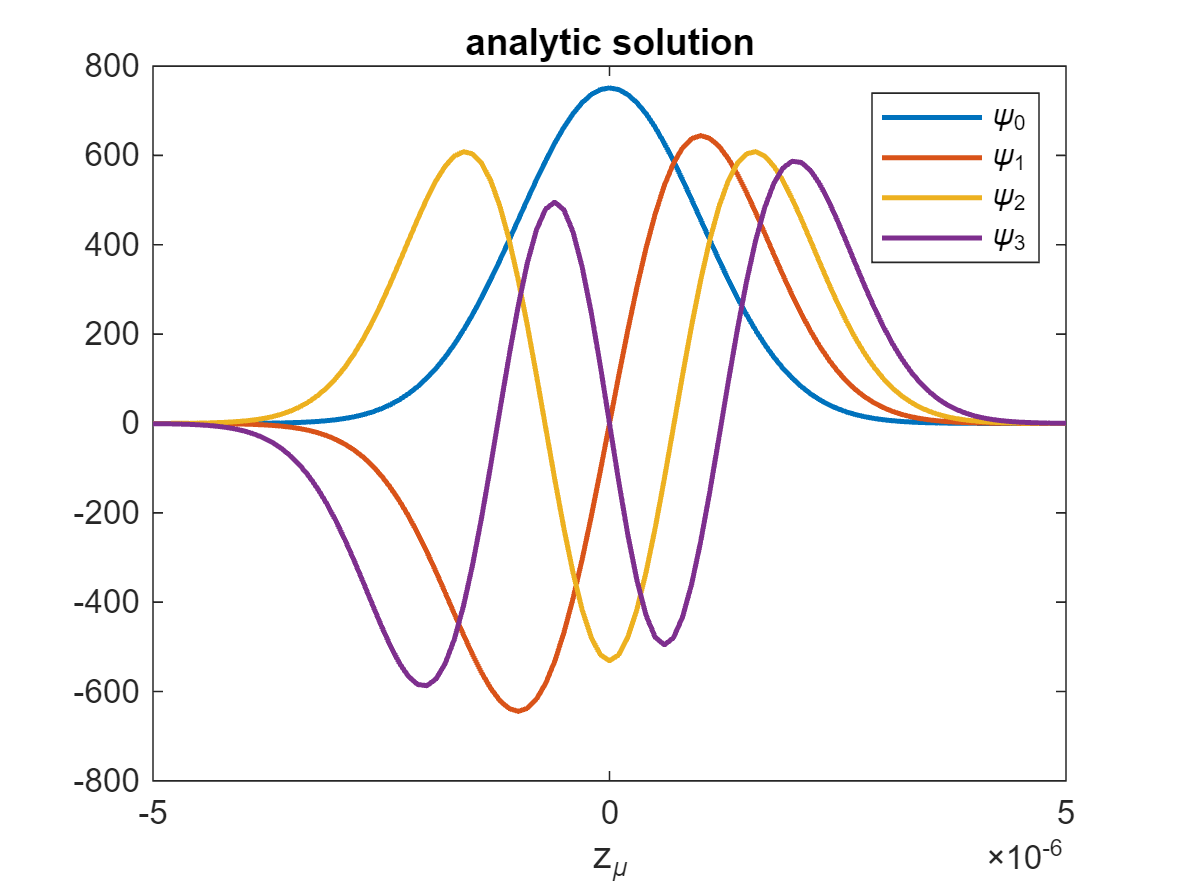

[PSI,~] = eigs(h,4,'smallestabs');
PSI0 = -PSI(:,1)./sqrt(deltaZ);
PSI1 = -PSI(:,2)./sqrt(deltaZ);
PSI2 = -PSI(:,3)./sqrt(deltaZ);
PSI3 = PSI(:,4)./sqrt(deltaZ);
% analytic solutions 
psi0 = (1/pi/z0^2)^(1/4)*exp(-z_mu.^2./(2*z0^2));
psi1 = (1/sqrt(2))*psi0.*hermiteH(1,z_mu/z0);
psi2 = (1/sqrt(8))*psi0.*hermiteH(2,z_mu/z0);
psi3 = (1/sqrt(48))*psi0.*hermiteH(3,z_mu/z0);

% plot analytic
figure(1);
plot(z_mu,psi0,'LineWidth',1.5);
hold on;
plot(z_mu,psi1,'LineWidth',1.5);
plot(z_mu,psi2,'LineWidth',1.5);
plot(z_mu,psi3,'LineWidth',1.5);
hold off;
xlabel('z_\mu');
title('analytic solution');
legend('\psi_0','\psi_1','\psi_2','\psi_3');

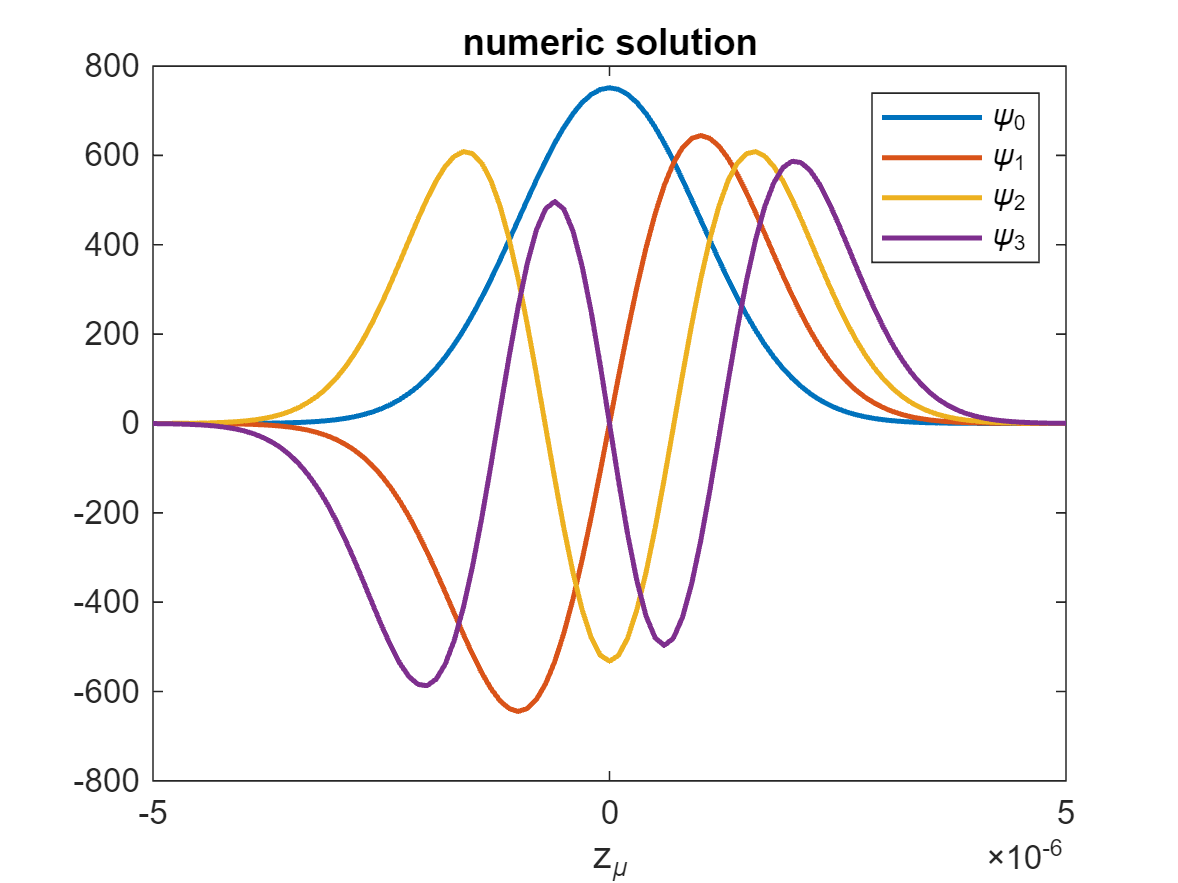


% plot numeric
figure(2);
plot(z_mu,PSI0,'LineWidth',1.5);
hold on;
plot(z_mu,PSI1,'LineWidth',1.5);
plot(z_mu,PSI2,'LineWidth',1.5);
plot(z_mu,PSI3,'LineWidth',1.5);
hold off;
xlabel('z_\mu');
title('numeric solution');
legend('\psi_0','\psi_1','\psi_2','\psi_3');

One crucial result coming from plotting the numeric solutions is that the fact that eigenvectors can be defined somewhat arbitrarily means that there might be extra negative signs attached to all of the components. this was the case for the first 3 eigenfunctions so they have been adjusted accordingly.

e.) $z_j = z_0\sqrt{2j + 1}$

The lattice approximation breaks down when $z_j \geq z_{max}/2$ or $j > j_{max} = (z_{max}/2\sqrt{2}z_0)^2
$

plot ratio $r_{j}= \frac{\epsilon_{j} - (j + 1/2)}{j + 1/2}\quad,\quad j=0,1,\dots,N$

jmax = (zmax/2/sqrt(2)/z0)^2

jmax = 12.5000

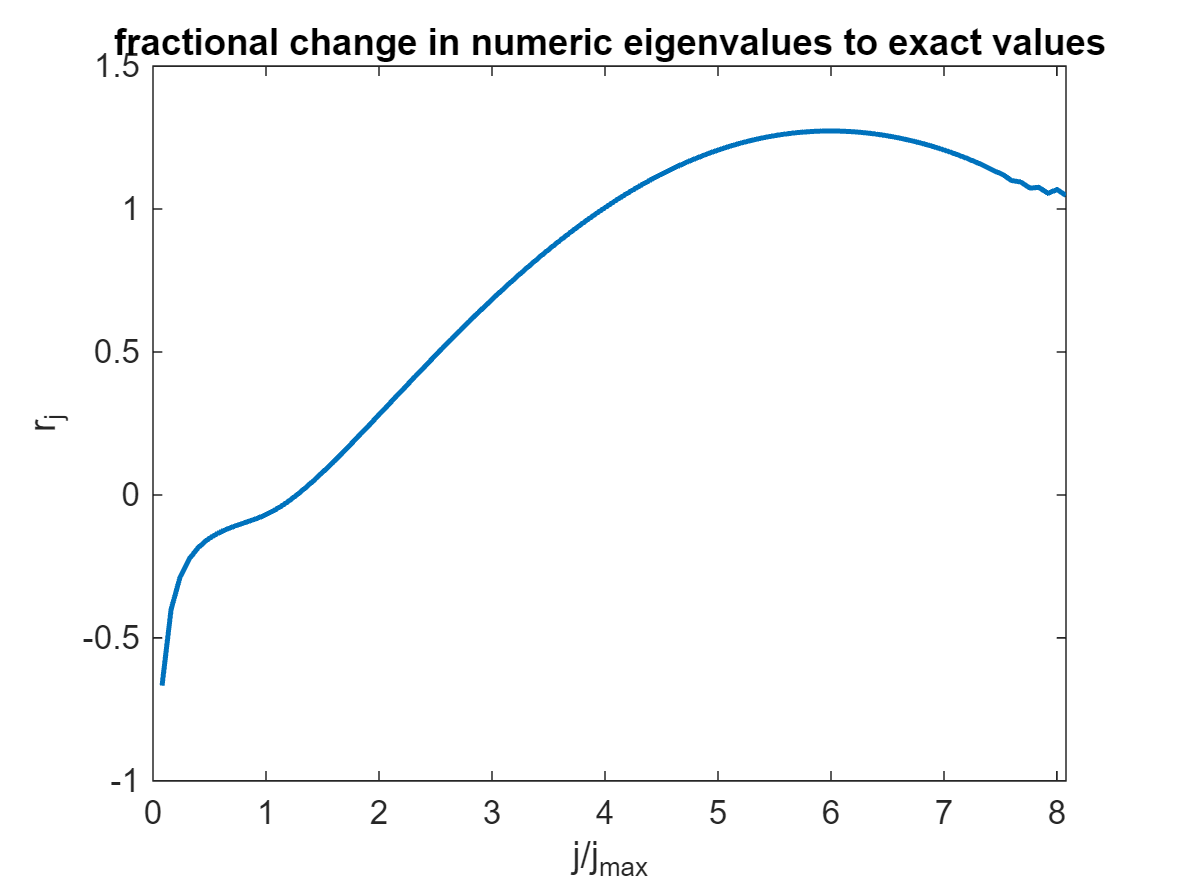

j = mu';
ej = eigs(h,N,'smallestabs'); % get the eigenvalues of h in vector form.
rj = (ej - (j + 1/2))./(j + 1/2);
figure(3);
plot(j./jmax,rj,'LineWidth',1.5);
ylabel('r_j');
xlabel('j/j_{max}');
title('fractional change in numeric eigenvalues to exact values');
xlim([0 max(j./jmax)]);
xticks(0:max(j./jmax)); % appropriate values are within j/jmax <= 1

#### D. Anharmonic oscillator


$$\Psi(z,t) = \sum\limits_{j=0}^{\infty} c_{j}\psi_{j}(z)e^\frac{-iE_{j}t}{\hbar}$$



$$c_{j} = \int_{-\infty}^{\infty}dz\; \psi_{j}^{*}\Psi(z,0)$$


Displaced wavefunction


$$\Psi_{\mu}(0) = \mathcal{N}_{0}\exp[-(z_{\mu} - 2z_{0})^{2}/2z_{0}^{2}]$$


a.) We want to make a 2D plot with respect to $\omega t$ and $\mu$ for the displaced wavefunction.

    1. Find the expansion coefficients

    2. Fill in the $E_j$ eigenvalues with the form $E_j = \hbar\omega(j + 1/2)$

    3. find $\Psi(z,t)$

    4. Plot $\Psi(z,t)$ 

1.) find expansion coefficients. To do this, we need to discretize the continuous expression above. 


$$\int_{-\infty}^{\infty} dz\; \psi_{j}^{*}(z)\Psi(z,0) \rightarrow \sum\limits_{\mu}\Delta z (\psi_{j}^{*})_{\mu}\Psi_{\mu}(0) = c_{j}$$


With this in mind, we should be able to find the set of expansion coefficients as follows: 

[V,~] = eigs(h,N,'smallestabs');
Ej = eigs(h,N,'smallestabs'); 
psi = V./sqrt(deltaZ); % from previous sections, we know this is the correct way to represent the wavefunction given the normalized eigenvectors
N0 = (1/pi/z0^2)^(1/4);
PSI0 = (N0.*exp(-(z_mu - 2*z0).^2/2/z0^.2))';
cj = psi'*PSI0*deltaZ; 

Important to realize is that since the hamiltonian for which we found the eigenvectors and and eigenvalues has $\hbar\omega$ factored out, we must consider this when we go about trying to write the time dependent form of the wavepacket.

If we write $E_{j}$  as  


$$e_{j} = \hbar\omega E_{j}$$


and 


$$\exp[-ie_{j}t/\hbar]\rightarrow\exp[-i\omega t E_{j}]$$


where $E_{j}= j + 1/2$ then it becomes straightforward how to inject time dependence.

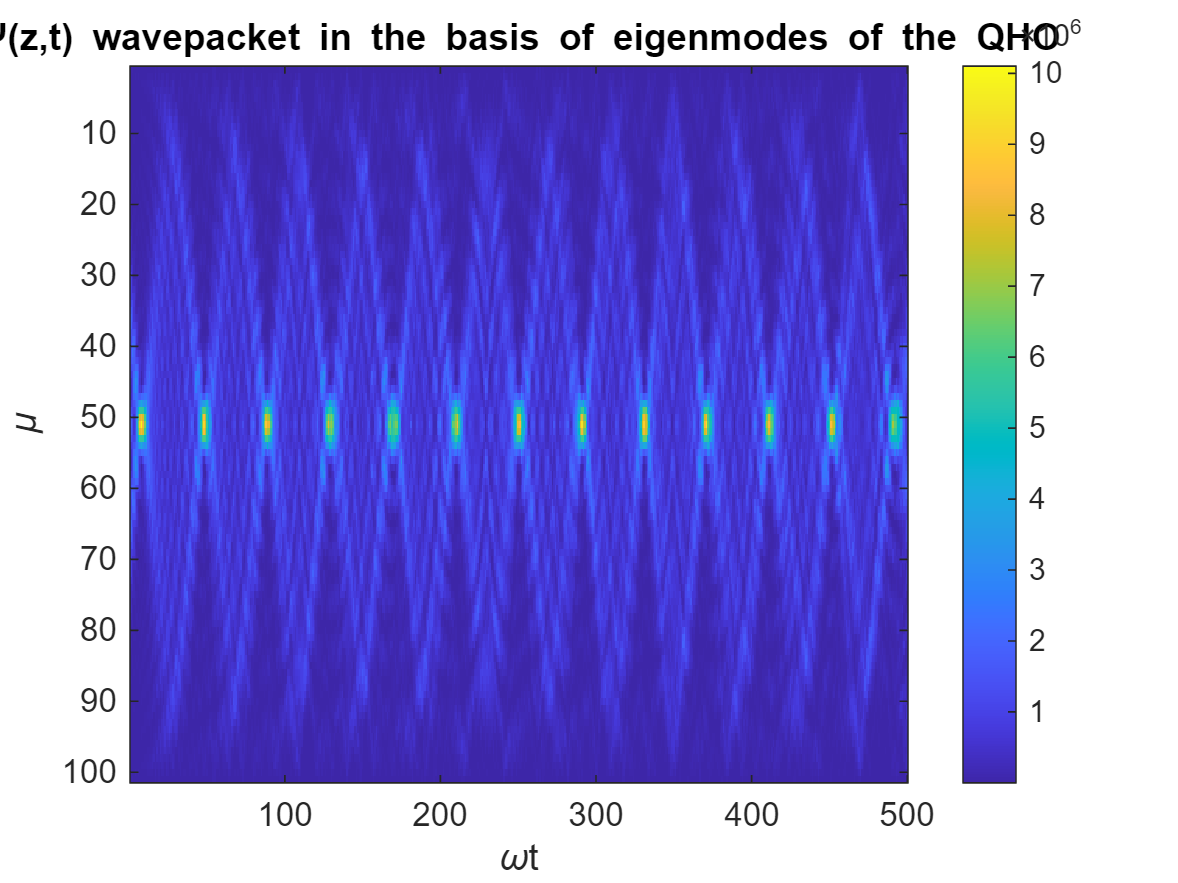

wt = linspace(1,40,500); % effective time vector
% wt = 1:40;
PSI_temp = zeros(length(cj),length(wt));
PSI = zeros(length(cj),length(wt));

for j = 1:length(cj)
    for k = 1:length(wt)
        PSI_temp(:,k) = cj(j)*psi(:,j)*exp(-1i*wt(k)*Ej(j));
    end
    if j == 1 
        PSI = PSI_temp;
    else
        % sum up the weighted eigenvectors
        PSI = PSI + PSI_temp;
    end
end
figure(4);
imagesc(abs(PSI).^2);
xlabel('\omegat');
ylabel('\mu');
title('\Psi(z,t) wavepacket in the basis of eigenmodes of the QHO')
colorbar;

% xlim([0,40]);

b.) plotting expectation values

$\langle z(t) \rangle/z_0 = 2\cos(\omega t )$ analytically 

To calculate the expectation value numerically, we need to take its definition


$$\langle z(t) \rangle = \langle \Psi(z,t) | z|\Psi(z,t)\rangle = \int_{-\infty}^{\infty} \Psi^{*}(z,t)z\Psi(z,t)\;dz$$
 

and discretize it :


$$\int_{-\infty}^{\infty} \Psi^{*}(z,t)z\Psi(z,t)\;dz \rightarrow \sum\limits_{\mu}\Delta z\Psi^{*}_{\mu}z_{\mu}\Psi_{\mu}$$


% analytic
braket_z_a = 2*cos(wt)

braket_z_a =     1.0806    0.9459    0.8054    0.6600    0.5106    0.3581    0.2034    0.0474   -0.1089   -0.2644   -0.4184   -0.5698   -0.7178   -0.8613   -0.9996   -1.1318   -1.2571   -1.3747   -1.4840   -1.5841   -1.6746   -1.7549   -1.8244   -1.8828   -1.9297   -1.9649   -1.9880   -1.9990   -1.9978   -1.9844   -1.9589   -1.9214   -1.8722   -1.8116   -1.7399   -1.6576   -1.5651   -1.4631   -1.3522   -1.2330   -1.1063   -0.9728   -0.8334   -0.6889   -0.5402   -0.3882   -0.2339   -0.0781    0.0782    0.2340


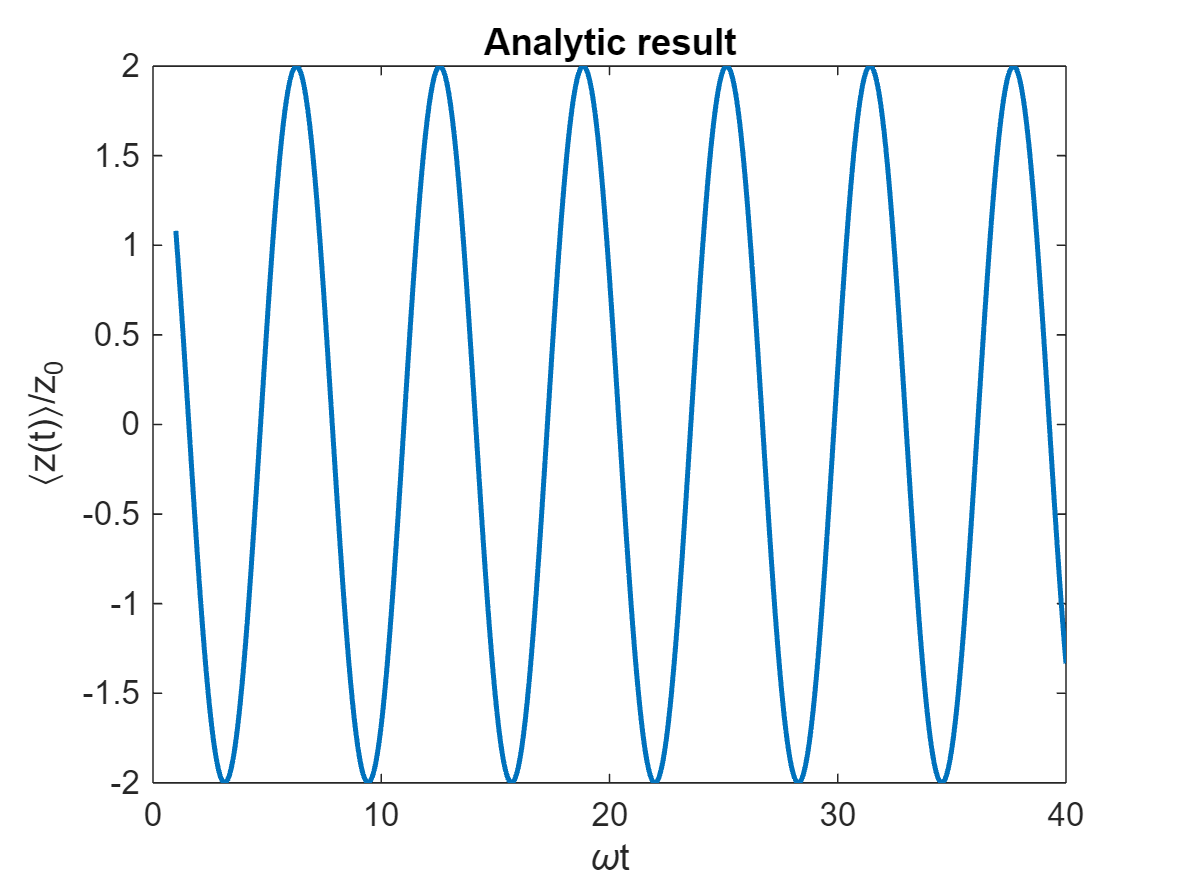


figure(5);
plot(wt,braket_z_a,'LineWidth',1.5);
title('Analytic result');
ylabel('\langlez(t)\rangle/z_0')
xlabel('\omegat');

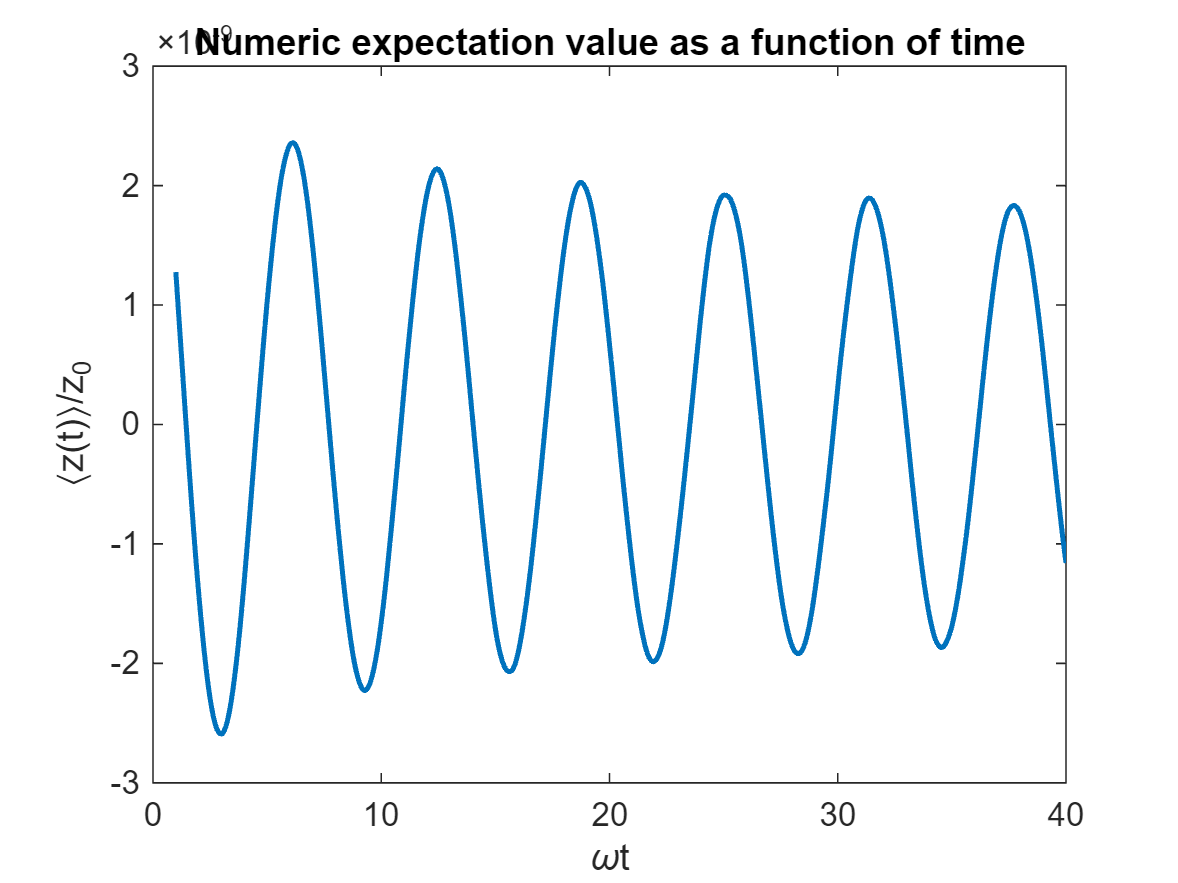

%% %% something is going wrong here.
% numeric
braket_z_n = zeros(1,length(wt));
PSI_conj = conj(PSI);
PSI;
for i = mu
     braket_z_n =  braket_z_n + z_mu(i).*abs(PSI(i,:)).^2;
end
braket_z_n = braket_z_n*deltaZ/z0;
figure(6);
plot(wt,real(braket_z_n),'LineWidth',1.5);
title('Numeric expectation value as a function of time')
ylabel('\langlez(t)\rangle/z_0');
xlabel('\omegat');

c.) Add anharmonicity to the harmonic oscillator.


$$V_{\mu} = \frac{1}{2}(z_{\mu}/z_{0})^{2}\rightarrow \frac{1}{2}(z_{\mu}/z_{0})^{2} + 0.02(z_{\mu}/z_{0})^{4}$$


This means that the normalized hamiltonian becomes


$$h_{\mu,\nu} = \frac{H_{\mu,\nu}}{\hbar\omega} = \bigl[\frac{1}{2}(z_{\mu}/z_{0})^{2} + 0.02(z_{\mu}/z_{0})^{4} + (z_{0}/\Delta z)^{2}\bigl]\delta_{\mu,\nu} - \frac{1}{2}(z_{0}/\Delta z)^{2}[\delta_{\mu,\nu+1} + \delta_{\mu,\nu-1}]$$


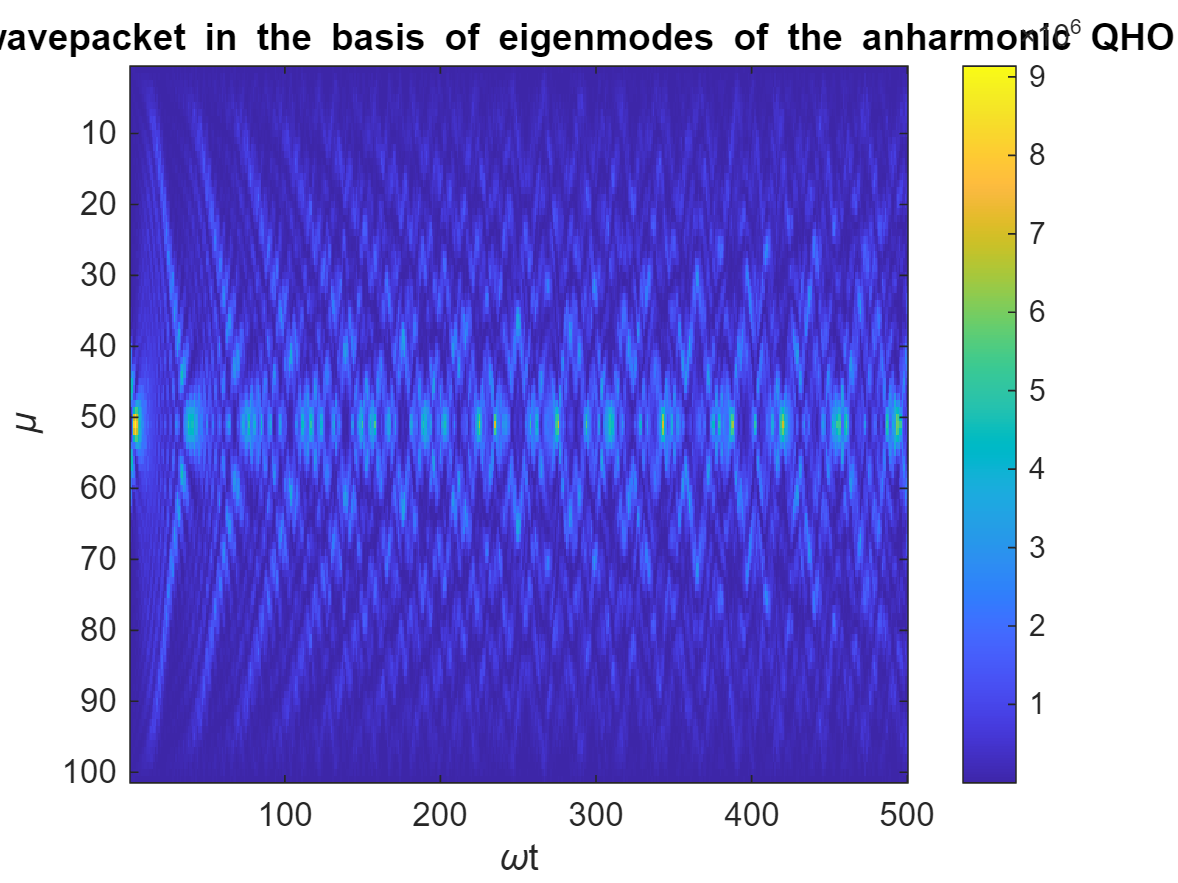

% clear psi V Ej PSI0 PSI PSI_temp cj
% Fill out the anharmonic hamiltonian matrix
h_a = zeros(N,N);
% create the hamiltonian matrix h
for i = 1:N
    for j = 1:N
        if i == j
            h_a(i,j) = (1/2)*(z_mu(i)/z0)^2 + 0.02*(z_mu(i)./z0).^(4) + (z0/deltaZ)^2;
        elseif i ==(j+ 1) || i == (j - 1)
            h_a(i,j) = -(1/2)*(z0/deltaZ)^2;
        end
    end
end

% get eigenvalues and eigen vectors
[V,~] = eigs(h_a,N,'smallestabs');
Ej_a = eigs(h_a,N,'smallestabs'); 
% fix normalization condition
psi_a = V./sqrt(deltaZ); % from previous sections, we know this is the correct way to represent the wavefunction given the normalized eigenvectors
% define the analytic normalization constant
N0 = (1/pi/z0^2)^(1/4);
% displaced wavefunction
PSI_a = (N0.*exp(-(z_mu - 2*z0).^2/2/z0^.2))';
% get the expansion coefficients.
cj_a = psi_a'*PSI_a*deltaZ; 

PSI_temp_a = zeros(length(cj_a),length(wt));
PSI_a = zeros(length(cj_a),length(wt));

% inject time dependence.
for j = 1:length(cj_a)
    for k = 1:length(wt)
        PSI_temp_a(:,k) = cj_a(j)*psi_a(:,j)*exp(-1i*wt(k)*Ej_a(j));
    end
    if j == 1 
        PSI_a = PSI_temp_a;
    else
        % sum up the weighted eigenvectors
        PSI_a = PSI_a + PSI_temp_a;
    end
end
figure(7);
imagesc(abs(PSI_a).^2);
xlabel('\omegat');
ylabel('\mu');
title('\Psi(z,t) wavepacket in the basis of eigenmodes of the anharmonic QHO')
colorbar;

% xlim([0,40]);

d.) plotting anharmonic expectation values.

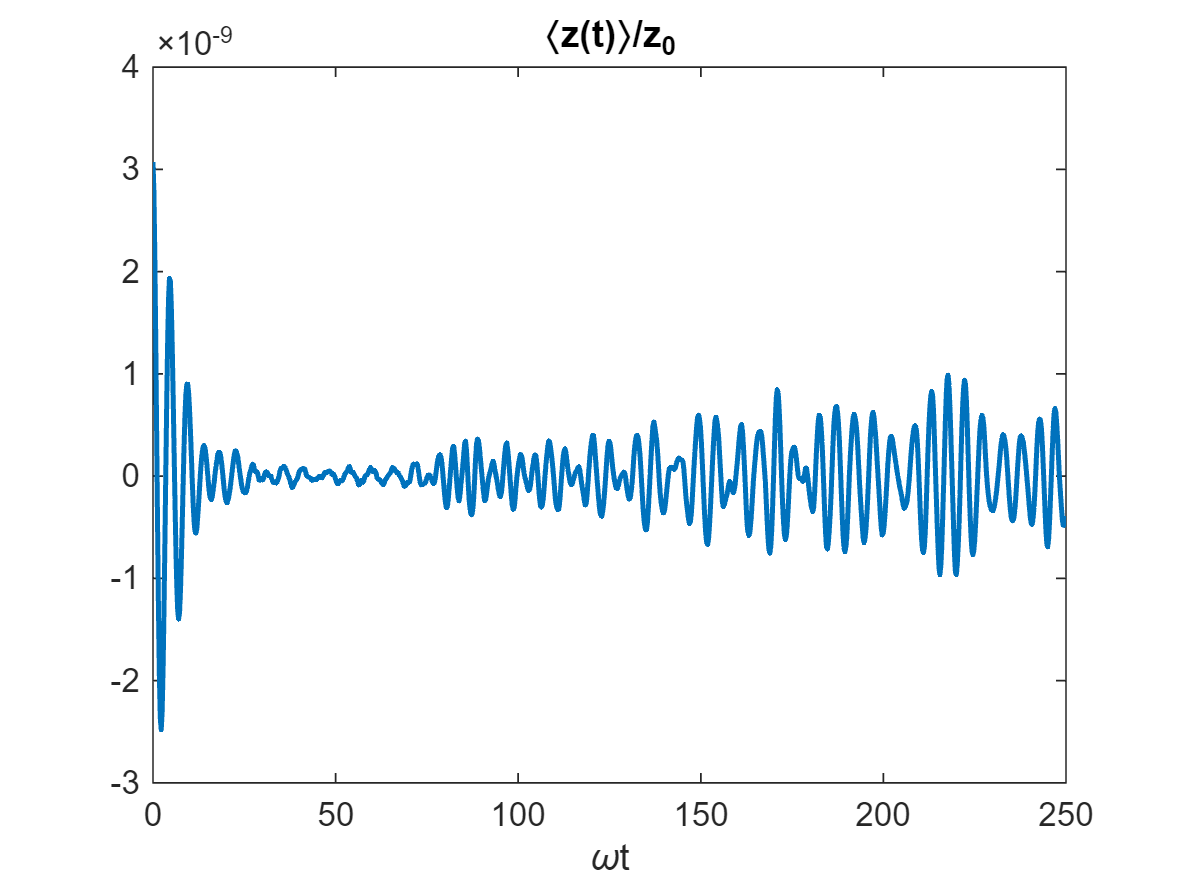

wt1 = linspace(0,250,1000);
% inject time dependence.
for j = 1:length(cj_a)
    for k = 1:length(wt1)
        PSI_temp_a(:,k) = cj_a(j)*psi_a(:,j)*exp(-1i*wt1(k)*Ej_a(j));
    end
    if j == 1 
        PSI_a = PSI_temp_a;
    else
        % sum up the weighted eigenvectors
        PSI_a = PSI_a + PSI_temp_a;
    end
end

braket_z_n_a = zeros(1,length(wt1));
PSI_conj_a = conj(PSI_a);
PSI;
for i = mu
     braket_z_n_a =  braket_z_n_a + z_mu(i).*abs(PSI_a(i,:)).^2;
end
braket_z_n_a = braket_z_n_a*deltaZ/z0;
figure(8);
plot(wt1,real(braket_z_n_a),'LineWidth',1.5);
title('\langlez(t)\rangle/z_0');
xlabel('\omegat');

## E. Double-well potential

 
$$V_{\mu} = \frac{1}{2}(z_{\mu}/z_{0})^{2}\rightarrow \frac{1}{2}(z_{\mu}/z_{0})^{2} + 4\exp(-2z_{\mu}^{2}/z_{0}^{2})$$


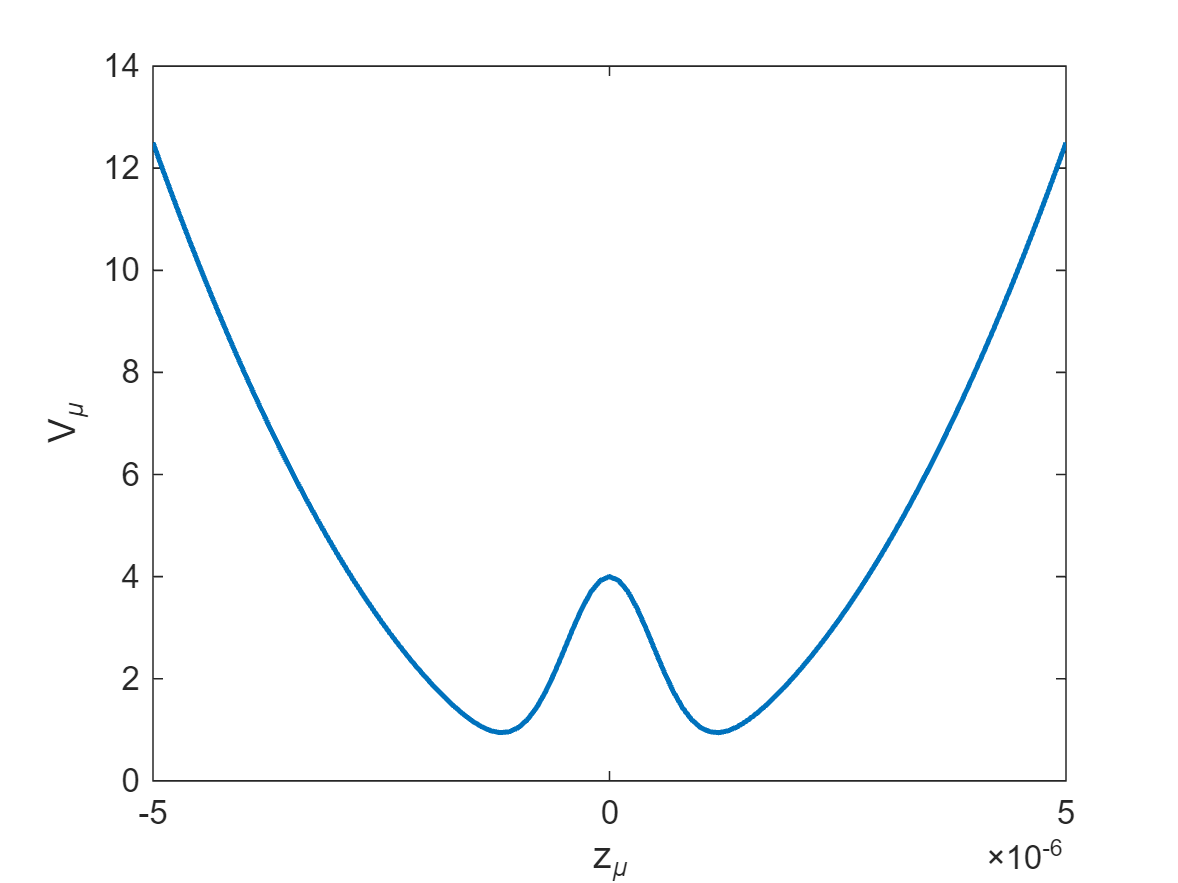

V_mu = 0.5*(z_mu./z0).^2 + 4*exp(-2*z_mu.^2./z0^2);
figure(9);
plot(z_mu,V_mu,'LineWidth',1.5);
ylabel('V_\mu');
xlabel('z_\mu');

a.) Displaced gaussian function


$$\Psi_{\mu}(0) = \mathcal{N}_{0}\exp[-(z_{\mu} - 1.3z_{0})^{2}/z_{0}^{2}]$$


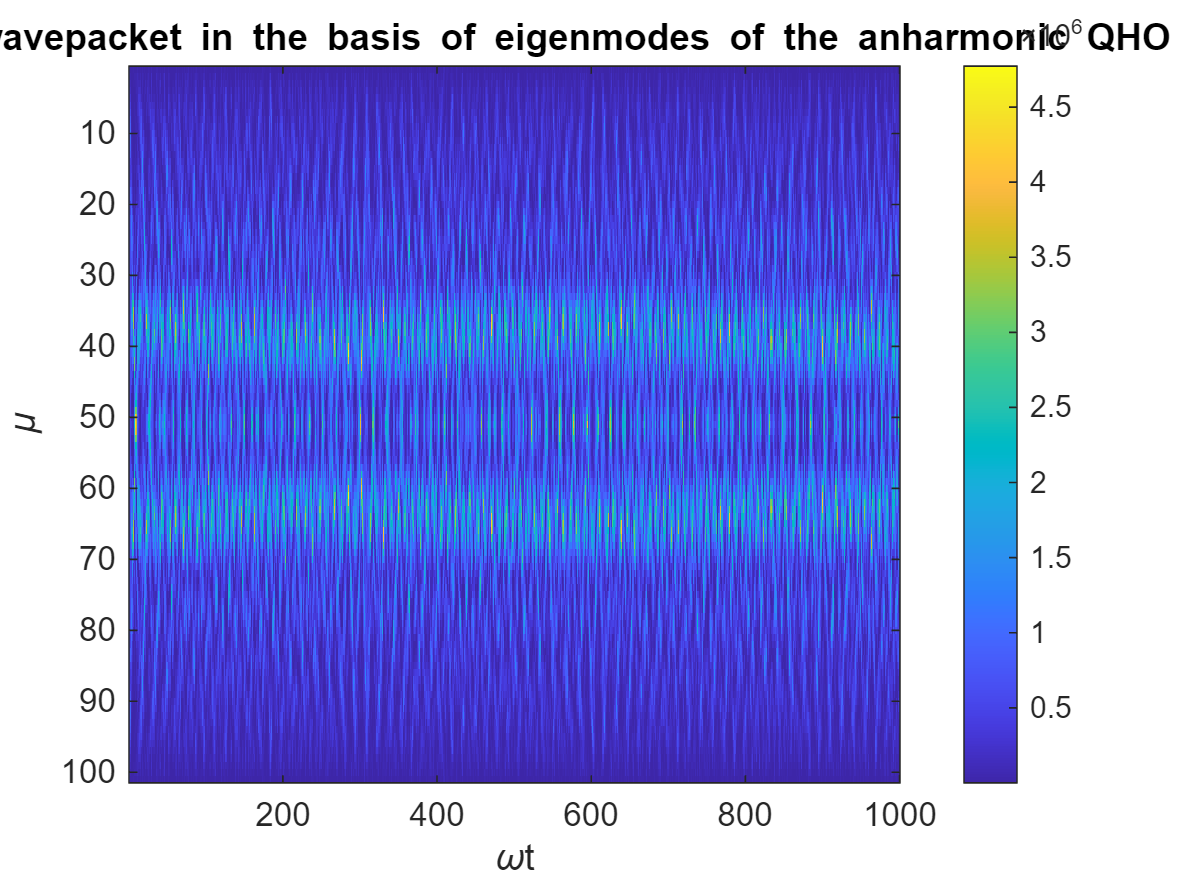

h_dw = zeros(N,N);
wt = linspace(0,204.6,1000);
% create the hamiltonian matrix h
for i = 1:N
    for j = 1:N
        if i == j
            h_dw(i,j) = (1/2)*(z_mu(i)/z0)^2 + 4*exp(-2*z_mu(i).^2./z0^2) + (z0/deltaZ)^2;
        elseif i ==(j+ 1) || i == (j - 1)
            h_dw(i,j) = -(1/2)*(z0/deltaZ)^2;
        end
    end
end

% get eigenvalues and eigen vectors
[V,~] = eigs(h_dw,N,'smallestabs');
Ej_dw = eigs(h_dw,N,'smallestabs'); 
% fix normalization condition
psi_dw = V./sqrt(deltaZ); % from previous sections, we know this is the correct way to represent the wavefunction given the normalized eigenvectors
% define the analytic normalization constant
N0 = (1/pi/z0^2)^(1/4);
% displaced wavefunction
PSI_dw = (N0.*exp(-(z_mu - 1.3*z0).^2/z0^.2))';
% get the expansion coefficients.
cj_dw = psi_dw'*PSI_dw*deltaZ; 

PSI_temp_dw = zeros(length(cj_dw),length(wt));
PSI_dw = zeros(length(cj_dw),length(wt));

% inject time dependence.
for j = 1:length(cj_dw)
    for k = 1:length(wt)
        PSI_temp_dw(:,k) = cj_dw(j)*psi_dw(:,j)*exp(-1i*wt(k)*Ej_dw(j));
    end
    if j == 1 
        PSI_dw = PSI_temp_dw;
    else
        % sum up the weighted eigenvectors
        PSI_dw = PSI_dw + PSI_temp_dw;
    end
end
figure(10);
imagesc(abs(PSI_dw).^2);
xlabel('\omegat');
ylabel('\mu');
title('\Psi(z,t) wavepacket in the basis of eigenmodes of the anharmonic QHO')
colorbar;

% xlim([0,40]);

b.) plot expectation values.

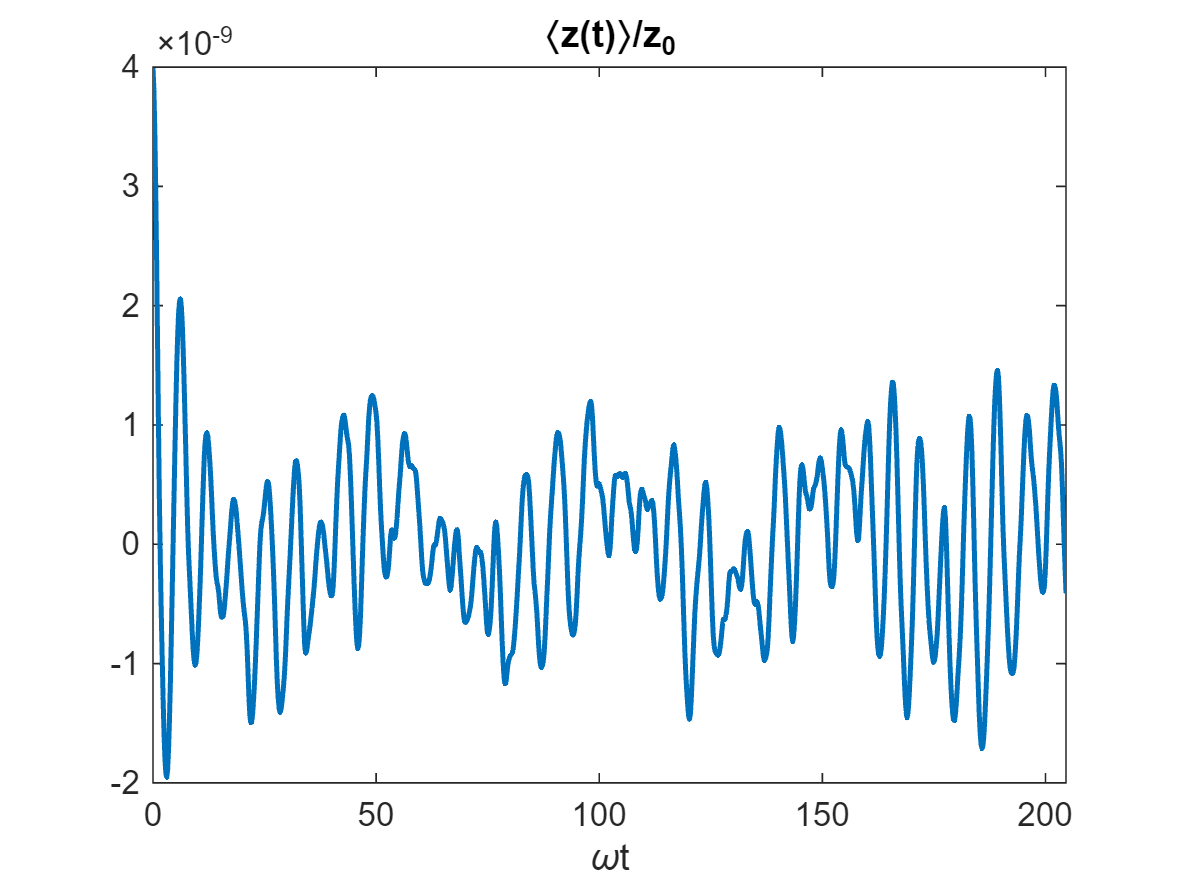

braket_z_n_dw = zeros(1,length(wt));
PSI_conj_dw = conj(PSI_dw);
for i = mu
     braket_z_n_dw =  braket_z_n_dw + z_mu(i).*abs(PSI_dw(i,:)).^2;
end
braket_z_n_dw = braket_z_n_dw*deltaZ/z0;
figure(11);
plot(wt,real(braket_z_n_dw),'LineWidth',1.5);
title('\langlez(t)\rangle/z_0');
xlabel('\omegat');
xlim([0, max(wt)]);

wt2 = 2*pi/(Ej_dw(2) - Ej_dw(1))

wt2 = 51.1552

% more or less this agrees with the period of the oscillations of the
% scaled expectation values.